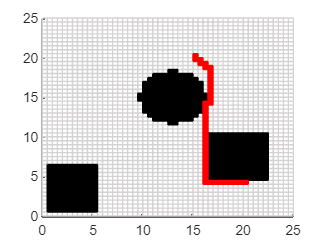

%%% definiowanie stałych, 
h = 25; % wysokość  [m]
w = 25; % szerokość [m]
n = 0.5;  % rozmiar komórki

sciezka_1 = load('sciezka_1_o.mat', 'path_1_o');
sciezka_2 = load('sciezka_2_o.mat');
sciezka_3 = load('sciezka_3_o.mat');

%%% zakłada się, że format danych przeszkód jest następujacy:
%%% ograniczamy się do kwadratow i kół
%%% przeszkoda ={"Typ wielokątu", [x0, y0] [a, b] albo r}
%%% w przypadku koła x0, y0 jest to środek, natomiast dla prostokątów jest
%%% to lewy dolny róg

prostokat_1 = {'Rectangle', [1, 1], [4, 5]};
prostokat_2 = {'Rectangle', [17, 5], [5, 5]};
kolo_1 = {'Circle', [5, 5], 3};
kolo_2 = {'Circle', [13, 15], 3};
kolo_3 = {'Circle', [17, 7], 3};
obstacles_data = {prostokat_1, prostokat_2, kolo_2};

grid_1 = make_grid(h, w, n, sciezka_1, obstacles_data, 1, 0);
%grid_2 = make_grid(h, w, n, sciezka_2, obstacles_data, 0, 2);
%grid_3 = make_grid(h, w, n, sciezka_3, obstacles_data, 0, 3);

s_loc = [20, 4];
e_loc = [15, 20];
A_path_g1 = Astar(s_loc, e_loc, grid_1, n);
show_path(A_path_g1, n)

%plot(A_path_g1(:, 1), A_path_g1(:, 2));

function [] = show_path(final_grid, n)
    for i = 1 : size(final_grid, 1)
        for j = 1 : size(final_grid, 2)
            if final_grid(i, j) == 2
                rectangle('Position', [i*n, j*n, n, n], 'FaceColor', 'r', 'EdgeColor', 'r')
            end
        end
    end
    
end

function path = Astar(start_location, end_location, occ_grid, n)
    % Utwórz listę otwartą, która będzie przechowywać komórki do odwiedzenia
    to_visit_cells = [start_location/n, 0, 0]; % Format: [x, y, f, parent_index]
    % Utwórz listę zamkniętą, która będzie przechowywać już odwiedzone komórki
    already_visited_cells = [];
    end_location = end_location/n;
    
    % Pobierz rozmiar siatki zajętości
    border_coordinates = size(occ_grid);
    
    % Główna pętla algorytmu A*
    while ~isempty(to_visit_cells)
        % Wybierz komórkę z najniższym kosztem f
        [~, index] = min(to_visit_cells(:, 3));
        current_cell = to_visit_cells(index, :);
        
        % Jeżeli wybrana komórka jest komórką końcową, zakończ algorytm
        if isequal(current_cell(1:2), end_location)
            
            path = reconstructPath(already_visited_cells, current_cell);
            %path = path*n; 
            real_grid = zeros(50);
            for i = 1 : size(path, 1)
                actual_cor = path(i, 1:2);
                real_grid(actual_cor(1), actual_cor(2)) = 2;
            end
            path = real_grid;
            return;
        end
        
        % Usuń wybraną komórkę z listy otwartej i dodaj ją do listy zamkniętej
        to_visit_cells(index, :) = [];
        already_visited_cells = [already_visited_cells; current_cell];
        
        % Wygeneruj sąsiadów wybranej komórki
        neighbors = generateNeighbors(current_cell(1:2), border_coordinates, occ_grid);
        
        % Iteruj przez sąsiadów
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i, :);
            
            % Sprawdź, czy sąsiad ma wartość 0 w occ_grid
            if occ_grid(neighbor(1), neighbor(2)) == 1
                continue; % Pomiń sąsiada, jeśli jest to przeszkoda
            end
            
            % Oblicz wartość f dla sąsiada
            g = current_cell(3) + 1; % Koszt dotarcia do sąsiada z punktu startowego
            h = norm(neighbor - end_location); % Odległość euklidesowa do punktu końcowego
            f = g + h; % Całkowity koszt
            
            
            % Jeśli sąsiad nie znajduje się na liście otwartej, dodaj go
            if ~any(ismember(neighbor, to_visit_cells(:, 1:2), 'rows'))
                to_visit_cells = [to_visit_cells; neighbor, f, size(already_visited_cells, 1)]; % Dodaj indeks rodzica
            else
                % Jeśli sąsiad znajduje się na liście otwartej, zaktualizuj wartość f jeżeli nowa droga jest krótsza
                index = find(ismember(to_visit_cells(:, 1:2), neighbor, 'rows'));
                if f < to_visit_cells(index, 3)
                    to_visit_cells(index, 3) = f;
                    % Zaktualizuj indeks rodzica
                    to_visit_cells(index, 4) = size(already_visited_cells, 1);
                end
            end
        end
    end
    
    % Jeśli lista otwarta jest pusta, a cel nie został osiągnięty, zwróć pustą ścieżkę
    path = [];
    disp('Nie można odnaleźć ścieżki.');
end

function path = reconstructPath(already_visited_cells, end_cell)
    % Inicjalizacja ścieżki
    path = [];
    % Ustaw bieżącą komórkę na końcową komórkę
    current_cell = end_cell;
    
    % Buduj ścieżkę od końca do początku
    while current_cell(4) ~= 0 % Dopóki istnieje komórka rodzica
        % Dodaj bieżącą komórkę do ścieżki
        path = [current_cell(1:2); path];
        % Znajdź komórkę rodzica na podstawie indeksu
        current_cell = already_visited_cells(current_cell(4), :);
    end
    % Dodaj komórkę początkową do ścieżki
    path = [current_cell(1:2); path];
end

function neighbors = generateNeighbors(cell_coordinates, border_coordinates ,occ_grid)
    % Generuj sąsiadów dla danej komórki
    x = cell_coordinates(1);
    y = cell_coordinates(2);
    
    % Możliwe przesunięcia względem bieżącej komórki
    %shifts = [-1, 0; 1, 0; 0, -1; 0, 1; 1 1; -1 -1; 1 -1; -1 1];
    shifts = [-1, 0; 1, 0; 0, -1; 0, 1];
    neighbors = [];
    for i = 1:size(shifts, 1)
        neighbor_x = x + shifts(i, 1);
        neighbor_y = y + shifts(i, 2);
        
        % Sprawdź, czy sąsiad mieści się w granicach siatki
        if neighbor_x >= 1 && neighbor_x <= border_coordinates(1) && neighbor_y >= 1 && neighbor_y <= border_coordinates(2) 
            if (occ_grid(neighbor_x, neighbor_y) == 0)
                neighbors = [neighbors; neighbor_x, neighbor_y];
            end
        end
    end
end

    
function occupancy_grid = make_grid(h, w, n, path, obstacles, show_grid, path_nr)
%%% określenie liczby potrzebnych prostokątów, trik polega na tym, że
%%% szukamy największy wspólny mianiownik i potem ograniczamy axisy
h_new = ceil(h/n) * n;
w_new = ceil(w/n) * n;

number_of_squares_h = h/n;
number_of_squares_w = w/n;
occupancy_grid = zeros(number_of_squares_h, number_of_squares_w);

figure(); hold on;
%%% wyrysowanie ściezki
if (path_nr == 1)
plot(path.path_1_o(:, 1), path.path_1_o(:, 2), 'LineWidth',2);
elseif (path_nr == 2)
plot(path.path_2_o(:, 1), path.path_2_o(:, 2), 'LineWidth',2);
elseif (path_nr == 3)
plot(path.path_3_o(:, 1), path.path_3_o(:, 2), 'LineWidth',2);
end
if show_grid
    %%% utworzenie grida
    for i = 0 : n : w_new
        for j = 0 : n : h_new
            rectangle('Position', [i, j, n, n], 'EdgeColor', [212, 210, 210]/255,...
    'LineWidth',0.5);
        end
    end
end


%%% pokolorowanie przeskód
%%% utworzenie grida
for i = 0 : n : h
    for j = 0 : n : w 
        for iterator = 1 : 1 : length(obstacles)
           shape_format = obstacles{iterator};
           if shape_format{1} == "Rectangle"

           %%% sprwadzamy typ prostokąt/kwadrat
           % Utworzenie zmiennych pomocniczych
            data = shape_format{2};
            sides = shape_format{3};
        
            % Wydobycie potrzebnych informacji
            x_bottom_left = data(1);
            y_bottom_left = data(2);
            width = sides(1);
            height = sides(2);
            x = i;
            y = j;
        
            % Wierzchołki komórki
            vertices = [x, y;
                        x + n, y;
                        x + n, y + n;
                        x, y + n];
        
        
            % Sprawdzenie czy punkt leży wewnątrz prostokąta
            inside_rectangle = 0;
            for k = 1 : 1 : 4
                x_punkt = vertices(k, 1);
                y_punkt = vertices(k, 2);
                if x_punkt >= x_bottom_left && x_punkt <= x_bottom_left + width && ...
                y_punkt >= y_bottom_left && y_punkt <= y_bottom_left + height
                    inside_rectangle = 1;
                    break;
                end
            end
            if inside_rectangle
                % Jeśli punkt leży wewnątrz prostokąta, narysuj kwadrat na czarno
                rectangle('Position', [i, j, n, n], 'FaceColor', 'k');
                
                occupancy_grid(int32(x/n), int32(y/n)) = 1;
            end

           %%% sprwadzenie czy należy do kółeczka UwU
           elseif shape_format{1} == "Circle"
               %utworzenie zmiennych pomocniczych
               data = shape_format{2};
               r = shape_format{3};
               
               %%% sprwadzenie czy kwadracik leży wewnatrz kola
               % Współrzędne środka koła
               x_centre = data(1);
               y_centre = data(2);

               x = i;
               y = j;
            
               % Wierzchołki komórki
               vertices = [x, y;
                           x + n, y;
                           x + n, y + n;
                           x, y + n];

               inside_circle = 0;
               
               for k = 1 : 1 : 4
                x_punkt = vertices(k, 1);
                y_punkt = vertices(k, 2);
                % Obliczenie odległości punktu od środka koła
                distance_1 = sqrt((x_punkt - x_centre)^2 + (y_punkt - y_centre)^2);
                % Sprawdzenie warunku
                if distance_1 <= r
                  inside_circle = 1;
                  break;
                end
               end

               % Sprawdzenie warunku
               if inside_circle
                 %%% narysuj kwadrat na czarno
                 rectangle('Position', [i, j, n, n], 'FaceColor','k');
                 occupancy_grid(int32(x/n), int32(y/n)) = 1;
               end
           end
        end
    end
end

%dodanie prawdziwych obwodów prawdziwych przeszkód
%kwadrat(1, 5, 1, 6);
%kwadrat(17, 22, 5, 10);
%circle(13, 15, 3)
axis([0 w 0 h]); 

end

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    plot(xunit, yunit, 'r');
end

function [] = kwadrat(x1, x2, y1, y2)
    line([x1, x2], [y1, y1], 'Color','red');
    line([x2, x2], [y1, y2], 'Color','red');
    line([x2, x1], [y2, y2], 'Color','red');
    line([x1, x1], [y2, y1], 'Color','red');
end
